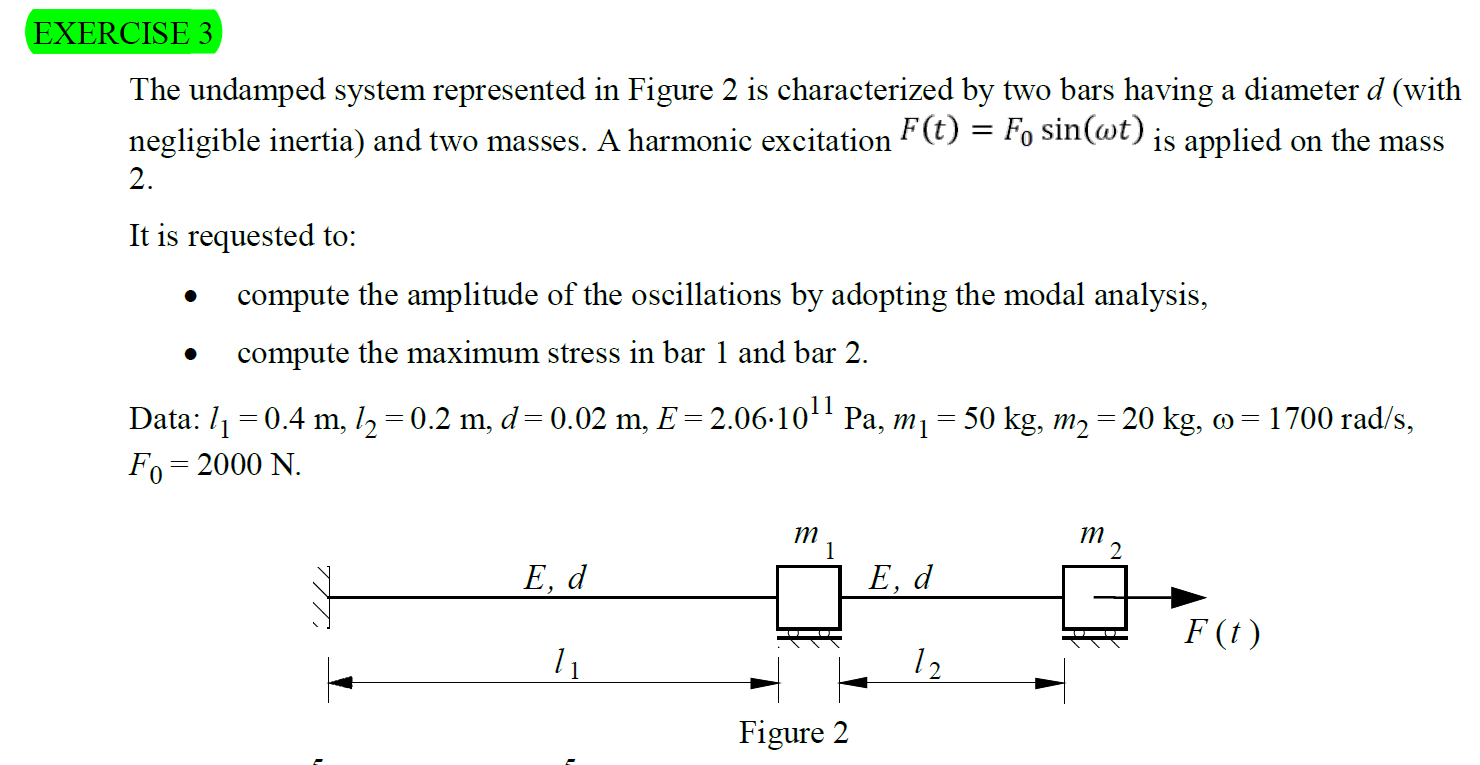

clear all
clc

m1=50;
m2=20;



k1=162*10^6;
k2=324*10^6;

M=[m1 0;0 m2];
K=[k1+k2 -k2;-k2 k2];


%solve the eigenproblem det(K-w^2*M)=0, obtaining two values of w^2
[phi,lambda]=eig(K,M);

wn1=sqrt(lambda(1,1))

wn1 = 1.4880e+03

wn2=sqrt(lambda(2,2))

wn2 = 4.8689e+03



%Compute modal mass, modal stiffness and modal forces
Mm=phi'*M*phi

Mm =     1.0000    0.0000
    0.0000    1.0000


Km=phi'*K*phi

Km = 	1.0e+07 *

    0.2214   -0.0000
   -0.0000    2.3706



phi

phi =    -0.1141   -0.0836
   -0.1321    0.1804




w=1.7*10^3;

syms x1 x2 x

eqn=(-M*w^2+K)*[x1 x2]'==[0 2000]';
[x10,x20]=solve(eqn);
double(x10)

ans = -4.6060e-05

double(x20)

ans = -4.8547e-05